% Image Object Vertices Visualizer

clear; close all;


% Select original video file
[vid_name,path1] = uigetfile('*.*', "Select a Video File");

% Select rotation vector (angle for each frame)
[blender_csv_name,path2] = uigetfile('*.*', "Select a Vertex Data File");
blender_mat = readmatrix(strcat(path2, blender_csv_name));

% PARAMETERS

% Dialog Box for Video Profile (file type)
profiles = {'Archival','Motion JPEG AVI','Motion JPEG 2000','MPEG-4', ...
            'Uncompressed AVI','Indexed AVI','Grayscale AVI'};
[lst_ind,~] = listdlg('PromptString', {'Select a Video File Format', '(Recommended: MPEG-4 or ','Uncompressed AVI):'}, ...
                      'SelectionMode', 'single', 'InitialValue', 4, ...
                      'ListSize',[150,100], ...
                      'ListString', profiles);

% Video Profile (File Type)
selected_profile = profiles{lst_ind};

% New Video Name
new_vid_name = strcat(vid_name, '__VERTEX_VISUAL');

% Create objects to read and write the video
v_reader = VideoReader(strcat(path1, vid_name));
v_writer = VideoWriter(new_vid_name, selected_profile);
% Make frame rates equal
v_writer.FrameRate = v_reader.FrameRate;
% Open the video file for writing
open(v_writer);

% Width & Height
v_width = v_reader.Width;
v_height = v_reader.Height;

% Preallocate
frame_new = zeros(v_height, v_width, 3);    % new frame size
incr = 0;                                   % increment

% Get Vertices Matrix
vert_mat = blender_mat(:,7:end);
% Format
vert_x = vert_mat(:, 1:2:end);  % x-values are odd
vert_y = vert_mat(:, 2:2:end);  % y-values are even
% Fix y-values
vert_y = v_height - vert_y;

% Display
vert_x

vert_x =    312   473   484   647
   312   473   483   647
   312   473   483   647
   311   473   483   646
   310   472   482   646
   309   472   481   645
   308   471   480   645
   306   470   478   644
   304   470   476   643
   302   469   475   642


vert_y

vert_y =    261   346   197   265
   261   346   197   265
   261   347   197   266
   262   347   198   266
   263   348   198   267
   264   349   200   268
   266   351   201   269
   267   352   202   270
   269   354   204   272
   271   356   206   273



Frame #1

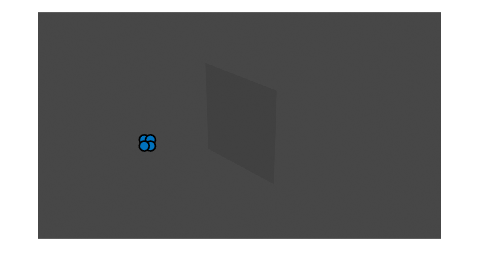

Index exceeds the number of array elements. Index must not exceed 1.

Error in circles_draw (line 40)
            if all(  centers(i,:) < ( dims([1,2]) - (radii(i)+(ring_width/2)) )  ) && all( centers(i,:) > (radii(i)+(ring_width/2)) )

% Create new video
while hasFrame(v_reader)
    incr = incr + 1;
    
    % Print what's happening
    print_str = strcat("\nFrame #", num2str(incr));
    fprintf(print_str);

    % get current frame
    frame = readFrame(v_reader);

    % 

    
    % Correctly Format Verteces
    num_verteces = length(vert_x(incr,:));
    centers = []; % clear for next frame
    for c = 1:num_verteces
        centers(c + (num_verteces*(incr-1)),:, incr) = [vert_y(incr,c), vert_x(incr,c)];
    end
    
    % Create new frame (insert rotation angle text)

    [frame_new, ~] = circles_draw(frame, centers(:,:,incr), 10, 1)

    % write new frame to new video
    writeVideo(v_writer, frame_new);

end


close(v_writer); % close the new video file

fprintf("\n>>> DONE <<<\n")